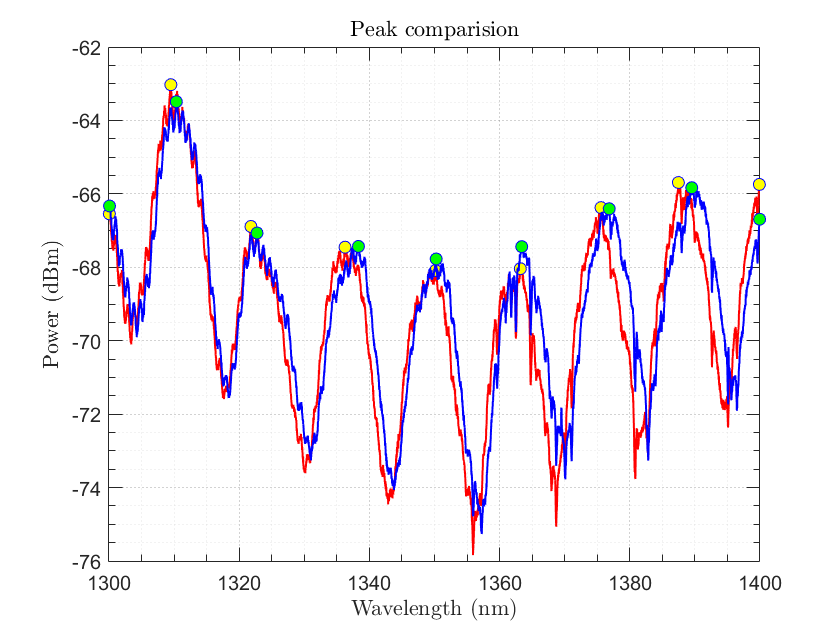

clear
% ==========================================================================
% Cambiar la ruta de lectura del archivo para leerlo en otra computadora 
% ==========================================================================
cd 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data';

data = readmatrix('W0036_Ref.CSV');
wavelength = data(:, 1);
power = data(:, 2);
wavelength(1:21) = [];
power(1:21) = [];
[peaks, locs] = findpeaks(power, 'MinPeakDistance', 450);
peak_distances = diff(wavelength(locs));
avg_distance = mean(peak_distances);
max_distance = max(peak_distances);

figure;
hold on
plot(wavelength, power, "LineWidth", 1.02, "Color", [1 0 0], 'DisplayName', 'Trace F');
plot(wavelength(locs), peaks, 'o', 'MarkerEdgeColor', 'blue', 'MarkerFaceColor', 'yellow', 'MarkerSize', 6, 'DisplayName', 'Peaks');
xlabel('Wavelength (nm)', 'Interpreter', 'latex');
ylabel('Power (dBm)', 'Interpreter', 'latex');
title('Peak comparision', 'Interpreter', 'latex');
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'TickLength', [0.02, 0.04], ...
    'LineWidth', 0.5);
grid minor;
set(gca, 'GridLineStyle', ':', ...
    'GridColor', [0.5, 0.5, 0.5], ...
    'GridAlpha', 0.7, ...
    'MinorGridLineStyle', ':', ...
    'MinorGridColor', [0.8, 0.8, 0.8], ...
    'MinorGridAlpha', 0.5);
box on

data2 = readmatrix('W0037_HighHumdity.CSV');
wavelength2 = data2(:, 1);
power2 = data2(:, 2);
wavelength2(1:21) = [];
power2(1:21) = [];
[peaks2, locs2] = findpeaks(power2, 'MinPeakDistance', 450);

hold on
plot(wavelength, power2, "LineWidth", 1.02, "Color", [0 0 1], 'DisplayName', 'Trace F');
plot(wavelength2(locs2), peaks2, 'o', 'MarkerEdgeColor', 'blue', 'MarkerFaceColor', [0 1 0], 'MarkerSize', 6, 'DisplayName', 'Peaks');